# International Gasoline Prices

Instructions are in the task pane to the left.

## Load data

gasprices = readtable("./data/gasprices.csv", "Range", "A5:K24");

Year = gasprices.Year;
Australia = gasprices.Australia;
Germany = gasprices.Germany;
Mexico = gasprices.Mexico;
Canada = gasprices.Canada;
hourlyAus = 22.95;
hourlyCan = 20.49;
hourlyGer = 20.29;
hourlyMex = 6.96;

## Convert prices

Convert the prices from USD/gallon to USD/liter using the conversion factor saved in the variable `gal2lit`.

gal2lit = 0.2642;
Australia = gal2lit * Australia;
Germany = gal2lit * Germany;
Mexico = gal2lit * Mexico;
Canada = gal2lit * Canada;

## Plot results

Plot the converted prices for the years 1990 to 2008.

plot(Year, Australia, "*--")
hold on
grid minor;
plot(Year, Germany, "*--")
plot(Year, Mexico, "*--")
plot(Year, Canada, "*--")
hold off

Annotate the plot

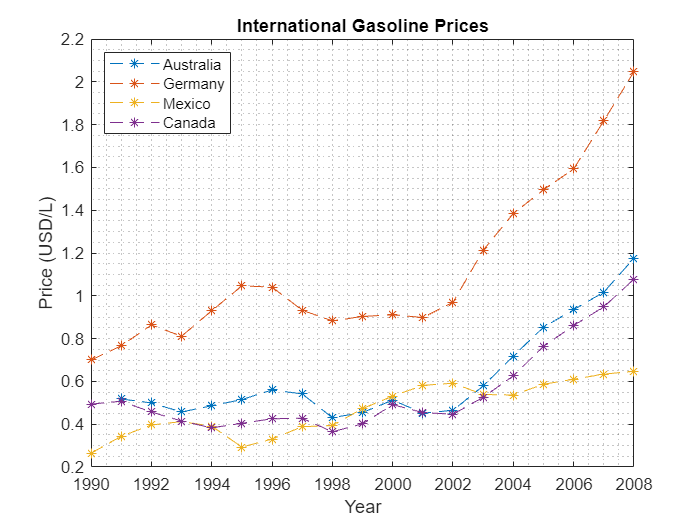

title("International Gasoline Prices")
xlabel("Year")
ylabel("Price (USD/L)")
legend("Australia", "Germany", "Mexico", "Canada", "Location", "northwest")

## Convert Price to "Hours Worked"

Convert the prices to cost in terms of hours worked to earn enough to buy a liter.

AustraliaH = Australia / hourlyAus;
GermanyH = Germany / hourlyGer;
MexicoH = Mexico / hourlyMex;
CanadaH = Canada / hourlyCan;

Notice that now Mexico is now as expensive as Germany and the two Commonwealth countries track each other pretty closely.

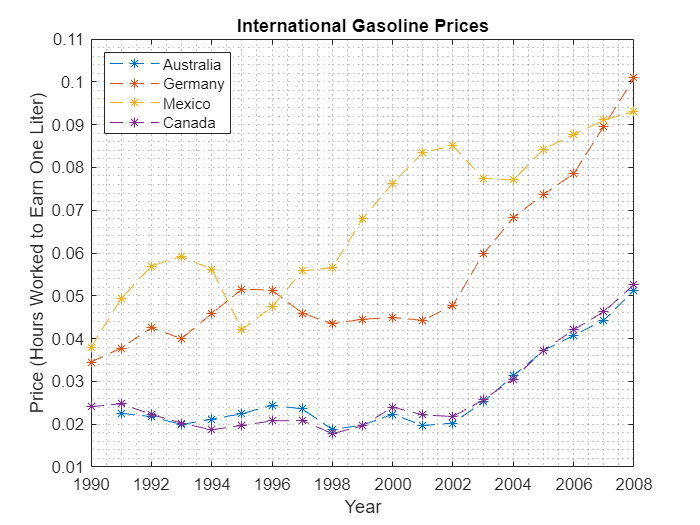

plot(Year, AustraliaH, "*--")
hold on
grid minor
plot(Year, GermanyH, "*--")
plot(Year, MexicoH, "*--")
plot(Year, CanadaH, "*--")
hold off
title("International Gasoline Prices")
xlabel("Year")
ylabel("Price (Hours Worked to Earn One Liter)")
legend("Australia", "Germany", "Mexico", "Canada", "Location", "northwest")